# QEA HW7

## 21.1

% Define and plot D
D = [-1 3;
      1 4;
      3 4;
      7 5;
     10 9]

D =     -1     3
     1     4
     3     4
     7     5
    10     9


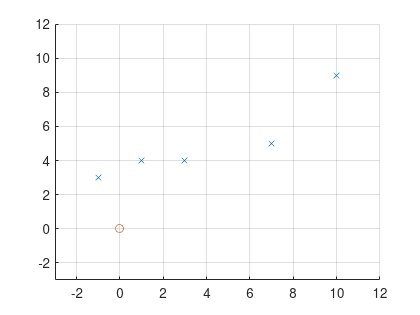


clf; hold on
plot(D(:, 1), D(:, 2), 'x')
plot(0,0, 'o')
xlim([-3 12])
ylim([-3 12])
grid on


% Mean-centered D
mu1 = mean(D(:, 1));
mu2 = mean(D(:, 2));
muD(:, 1) = D (:, 1) - mu1;
muD(:, 2) = D (:, 2) - mu2;

figure; clf
hold on
plot(muD(:, 1), muD(:, 2), 'x')
xlim([-7 7])
ylim([-7 7])
grid on

% Covariance Matrix
covD = (1/4)* (muD'*muD)

covD =    20.0000    9.5000
    9.5000    5.5000


[vectors, values] = eig(covD)

vectors =     0.4435   -0.8963
   -0.8963   -0.4435


values =     0.7996         0
         0   24.7004


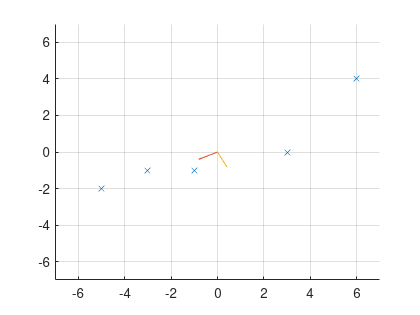

quiver(0,0,vectors(1,2),vectors(2,2)) % principal eigenvector
quiver(0,0,vectors(1,1),vectors(2,1)) % 2nd eigenvector

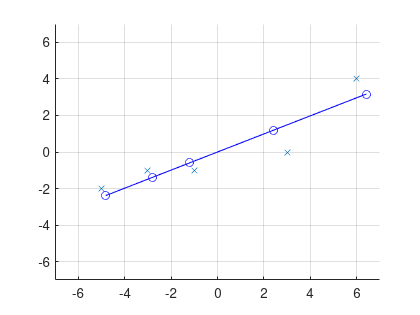


% Projection
projection = muD * vectors(:, 2);
B = projection * vectors(:, 2)';

figure; clf
hold on
plot(muD(:, 1), muD(:, 2), 'x')
plot(B(:,1), B(:,2), 'bo')
plot(B(:,1), B(:,2), 'b')
xlim([-7 7])
ylim([-7 7])
grid on

## 21.2

- It is impossible to recover D perfectly from B because by reducing its dimensionality, we have lost the data in the direction perpendicular to the principal eigenvector, and that data cannot be brought back.

- This would be a different, nonoptimal way of reducing the dimensionality of the data. It would store the information in the perpendicular direction to p1

- We can quantify how well we represented B simply by subtracting B - D

- We can do this by multiplying the eigenvector matrix by d, which would give us the weights to then multiply each eigenvector by to reach the original data point

## 21.3

load avg_temperatures_pt2.mat
% means
temps = [b_tr w_tr s_tr];
mub = mean(temps(:, 1));
muw = mean(temps(:, 2));
mus = mean(temps(:, 3));
% mean centering
muTemps = [b_tr-mub w_tr-muw s_tr-mus];
% covariance matrix
R = (1/7304)*(muTemps'*muTemps);
% eigenthings
[vectors, values] = eig(R);
vp = [vectors(:, 3) vectors(:, 2)];

% new temps setup
mubn = mean(b_new);
muwn = mean(w_new);
musn = mean(s_new);
muNewTemps = [b_new-mubn w_new-muwn s_new-musn]';

% compression
compressed = vp' * muNewTemps

compressed =    36.6821   26.3878   31.2968   16.8807   18.4982   46.5426   47.2158   61.2303   41.4033   46.1820   44.4077   28.6679   34.0365   45.4352   36.6785   33.4268   43.9758   31.1840   19.4096   29.1512   31.2076   27.8636   29.7911   28.3601   24.8128   36.2388   43.1416   45.6929   41.5703   29.4826   46.1816   41.3057   36.1873   48.6007   35.9801   29.1175   51.4298   36.8611   29.1392   37.7182   39.8178   38.4176   38.9528   51.9951   47.8984   51.6441   63.2136   53.5366   44.6594   47.3110
    5.1664    7.0783   -0.4829    1.1474    0.5159   -1.8417    0.1960   -3.1030    4.2373    6.4462    3.7690    4.7241    4.2555    1.1629    2.8408    2.6382    4.1884    7.5523    8.6955    7.3671    2.1715   -2.7677   -4.1784   -2.3330    1.5410   -1.3966   -1.6306   -0.4093    1.1602   -1.1000   -7.8427   -3.7746   -3.1104   -3.8057   -3.0483   -5.2906  -10.0012   -5.2057   -2.4132   -0.6365   -0.9196    1.1244    5.4861    1.4833   -1.8809   -4.9050   -9.6776   -5.6352   -5.

unpacked = vp * compressed

unpacked =   -25.0304  -17.6247  -21.9103  -11.6582  -12.8593  -32.7110  -32.9500  -43.1109  -28.4327  -31.5192  -30.5838  -19.4839  -23.2861  -31.5969  -25.2915  -23.0438  -30.2347  -20.9202  -12.5682  -19.5217  -21.5470  -19.7719  -21.2779  -20.0693  -17.1528  -25.4651  -30.3120  -31.9552  -28.8983  -20.7134  -33.1394  -29.2731  -25.6235  -34.3710  -25.4717  -20.9337  -37.0493  -26.3316  -20.6225  -26.4120  -27.9103  -26.7007  -26.5798  -36.1416  -33.6623  -36.6209  -45.2416  -38.0253  -31.8276  -33.3090
  -25.1092  -17.7139  -21.9301  -11.6825  -12.8788  -32.7296  -32.9889  -43.1288  -28.5061  -31.6179  -30.6551  -19.5522  -23.3540  -31.6438  -25.3478  -23.0955  -30.3097  -21.0179  -12.6676  -19.6159  -21.5925  -19.7669  -21.2608  -20.0689  -17.1872  -25.4799  -30.3300  -31.9870  -28.9421  -20.7258  -33.0996  -29.2689  -25.6217  -34.3722  -25.4704  -20.9052  -36.9927  -26.3101  -20.6220  -26.4353  -27.9326  -26.7417  -26.6634  -36.1967  -33.6816  -36.6139  -45.1973  -38.0127  -31.80

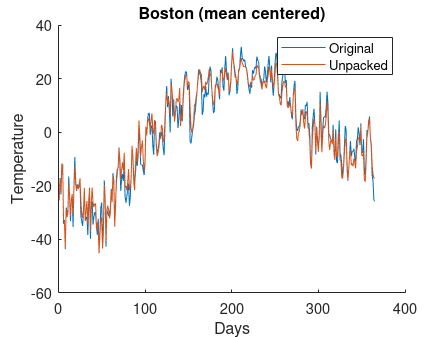


% plotting
figure; hold on; title("Boston (mean centered)")
plot(muNewTemps(1, :))
plot(unpacked(1, :))
legend('Original', 'Unpacked')
xlabel('Days')
ylabel('Temperature')

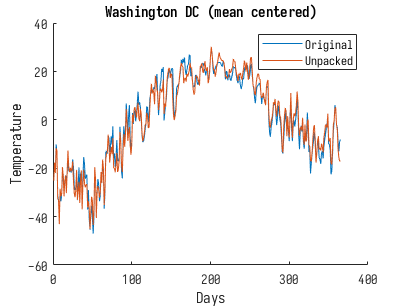


figure; hold on; title("Washington DC (mean centered)")
plot(muNewTemps(2, :))
plot(unpacked(2, :))
legend('Original', 'Unpacked')
xlabel('Days')
ylabel('Temperature')

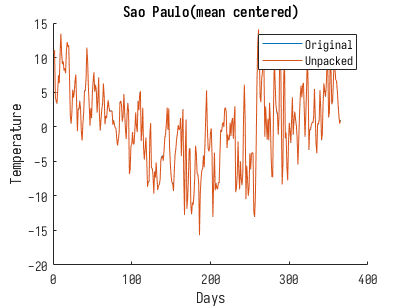


figure; hold on; title("Sao Paulo(mean centered)")
plot(muNewTemps(3, :))
plot(unpacked(3, :))
legend('Original', 'Unpacked')
xlabel('Days')
ylabel('Temperature')

7. With all 3 eigenvectors, theoretically I should be able to perfectly recover the original dataset, as we are simply changing into an eigenbasis and back without losing any data.

## 21.4

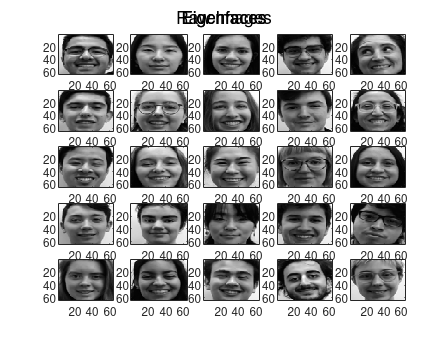

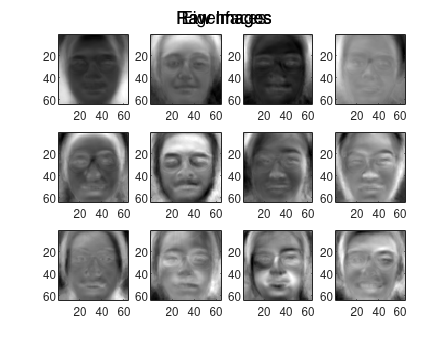

accuracy = 0.9803

time = 1.2289

[accuracy, time] = eigenfaces(true)

[accuracy, time] = eigenfaces(false)

accuracy = 0.9803

time = 0.6446

As can be seen by the prior two examples, one of the simplest things that can be done to reduce execution time is to simply not print out as much output. 

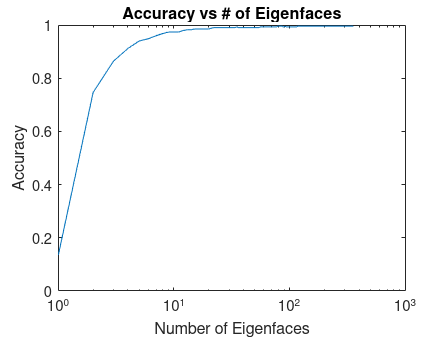

tic
vectors = eigenvectors(300, false);
accuracies = NaN(1, 300);
for i=1:300
    accuracies(i) = indAccuracy(vectors(:, 1:i), false);
end
figure;
semilogx(accuracies)
xlabel('Number of Eigenfaces')
ylabel('Accuracy')
title('Accuracy vs # of Eigenfaces')

toc

Elapsed time is 87.650621 seconds.


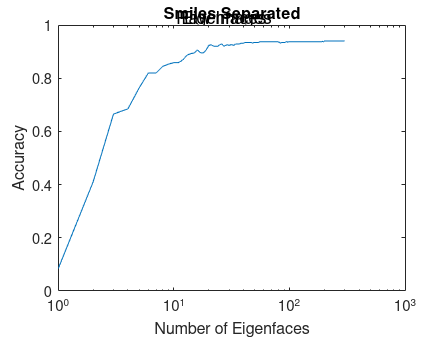

tic
vectors = eigenvectors(300, true);
accuracies = NaN(1, 300);
for i=1:300
    accuracies(i) = indAccuracy(vectors(:, 1:i), true);
end
figure;
semilogx(accuracies)
xlabel('Number of Eigenfaces')
ylabel('Accuracy')
title('Smiles Separated')

toc

Elapsed time is 51.810440 seconds.


The model had more trouble when the smiles and non-smiles were separated out; It did reach 90% accuracy, but not until using 19 eigenfaces, while on the original model it was able to achieve 98% with just 12. 

*Note that I have stopped at 300 eigenfaces out of a maximum 4096 just in the interest of saving time - the variation past then is barely perceptible

publish("eigenfaces.m", "pdf");

Not enough input arguments.

Error in eigenfaces (line 12)
    if verbose



ans = '/home/amit/Documents/QEA/Faces/html/eigenfaces.pdf'

publish("eigenvectors.m", 'pdf');

Not enough input arguments.

Error in eigenvectors (line 2)
    if smile_separated == false



ans = '/home/amit/Documents/QEA/Faces/html/eigenvectors.pdf'

publish("indAccuracy.m", 'pdf');

Not enough input arguments.

Error in indAccuracy (line 2)
    if smile_separated == false



ans = '/home/amit/Documents/QEA/Faces/html/indAccuracy.pdf'